%% Idée pour temps de fonctionnement :
% somme de l'heure i à i+UT-1 des états > UT*dem(i)
% somme de l'heure i à i+DT-1 des (1-états) > DT*arret(i)

clear

importOptions = spreadsheetImportOptions();

importOptions.Sheet = "Tableaux2et3et4";
importOptions.VariableNames = ["Unit", "Node", "Fuel", "Pmin", "Pmax", "Rpos", "Rneg", "RU", "RD", "UT", "DT", "C", "CRpos", "CRneg", "Csu", "Pini", "Uini", "Tini", "Emissions"];
importOptions.VariableTypes = ["double", "double", "categorical", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double"];
importOptions.DataRange = "A3:S14";

dataC = readtable('Donnees_Projet_Optimisation.xlsx', importOptions);

importOptions = spreadsheetImportOptions();
importOptions.Sheet = "Tableau1";
importOptions.VariableNames = ["H", "D"];
importOptions.VariableTypes = ["double", "double"];
importOptions.DataRange = "A2:B25";

dataD = readtable('Donnees_Projet_Optimisation.xlsx', importOptions);
clear importOptions

% Standardisation des données
% min --> h
dataC.RU = dataC.RU*60;
dataC.RD = dataC.RD*60;

% Données
h = length(dataD.H);
c = length(dataC.Unit);
n = c*h;
partR = 0.1;  % Niveau de sécurité pour la réserve (pourcentage de la demande)


%% Fonction obj
% X : 24*12*5 paramètres
% X : [C1(1), C1(2), ...,  i1(1), ...,  dem1(1), ...,  Rp(1), ...,  Rn(1), ...]
%    P : puissance
%    i : état
%    dem : démarrage
%    arr : arrêt
%    Rp : réserve positive
%    Rn : réserve négative

intcon = n+1:4*n;
% Nombre params : 6*n
f_obj = @(P) sum(reshape(P(1:n), 24, 12)*dataC.C);

f_lin = [reshape((dataC.C*ones(1, h))', 1, n), ...
    zeros(1, n), ...
    reshape((dataC.Csu*ones(1, h))', 1, n), ...
    zeros(1, n), ...
    reshape((dataC.CRpos*ones(1, h))', 1, n), ...
    reshape((dataC.CRneg*ones(1, h))', 1, n)];

nParam = 6*n;

% 2e fn onjectif pour multiobj :
f_lin2 = [reshape((dataC.Emissions*ones(1, h))', 1, n)*1e-3,...    % *1e-3 car émissions en t/GWh
    zeros(1, 5*n)];

%% Contrainte égalités
% Demande
D_eq = repmat(eye(h), 1, c);
bD_eq = dataD.D;

% Réserve positive
Rp_eq = repmat(eye(h), 1, c);
bRp_eq = dataD.D*partR;

% Réserve négative
Rn_eq = repmat(eye(h), 1, c);
bRn_eq = dataD.D*partR;

% Matrice égalité
Aeq = [D_eq, zeros(h, nParam-n);
    zeros(h, 4*n), Rp_eq, zeros(h, nParam-5*n);
    zeros(h, 5*n), Rn_eq, zeros(h, nParam-6*n)];
beq = [bD_eq ; bRp_eq ; bRn_eq];

%% Contraintes inégalité
% RD
RU_ineq = eye(n);
bRU_ineq = reshape((dataC.RU*ones(1, h))', n, 1);
diago = zeros(1, n-1);
for i=0:c-1
    diago(i*h+1:(i+1)*h-1) = -ones(1, h-1);
    bRU_ineq(i*h+1) = bRU_ineq(i*h+1) + dataC.Pini(i+1);
end
RU_ineq = [RU_ineq + diag(diago, -1), zeros(n)];

% RU
RD_ineq = -eye(n);
bRD_ineq = reshape((dataC.RD*ones(1, h))', n, 1);
diago = zeros(1, n-1);
for i=0:c-1
    diago(i*h+1:(i+1)*h-1) = ones(1, h-1);
    bRD_ineq(i*h+1) = bRD_ineq(i*h+1) - dataC.Pini(i+1);
end
RD_ineq = [RD_ineq + diag(diago, -1), zeros(n)];

% Réponse à la demande  : somme(Pi(k)) > D(k)
D_ineq = repmat(-eye(h), 1, c);
bD_ineq = -dataD.D;

% Réponse à la demande  : somme(Pi(k)) < D(k)
D_ineq = [D_ineq ; repmat(eye(h), 1, c)];
bD_ineq = [bD_ineq ; dataD.D];

% On/off : Pmin(i)*ii(k) - Pi(k) < 0
Pmin_ineq = [-eye(n), diag(reshape((dataC.Pmin*ones(1, h))', n, 1))];   % Explication : (dataC.Pmin*ones(1, h))' : [Pmin(1) ... Pmin(1);Pmin(2) ... Pmin(2) ; .. ; Pmin(c) ... Pmin(c)]
bmin_ineq = zeros(n, 1);

% On/off : Pi(k) - Pmax(i)*ii(k) < 0.001
Pmax_ineq = [eye(n), -diag(reshape((dataC.Pmax*ones(1, h))', n, 1))];
bmax_ineq = zeros(n, 1);

% Matrices finales Puiss et état
Aineq_2n = [RU_ineq ; RD_ineq ; Pmin_ineq ; Pmax_ineq];
bineq_2n = [bRU_ineq ; bRD_ineq ; bmin_ineq ; bmax_ineq];

% Variable de démarage : h+1 - h - Dem < 0
Dem_ineq = eye(n);
bDem_ineq = zeros(n, 1);
diago = zeros(1, n-1);
for i=0:c-1
    diago(i*h+1:(i+1)*h-1) = -ones(1, h-1);
    bDem_ineq(i*h+1) = dataC.Uini(i+1);
end
Dem_ineq = [Dem_ineq + diag(diago, -1), -eye(n)];

% Variable de démarage : h - h+1 + 2*Dem < 1
Dem1_ineq = -eye(n);
bDem1_ineq = ones(n, 1);
diago = zeros(1, n-1);
for i=0:c-1
    diago(i*h+1:(i+1)*h-1) = ones(1, h-1);
    bDem1_ineq(i*h+1) = 1 - dataC.Uini(i+1);
end
Dem1_ineq = [Dem1_ineq + diag(diago, -1), 2*eye(n)];

Dem_ineq = [Dem_ineq ; Dem1_ineq];
bDem_ineq = [bDem_ineq ; bDem1_ineq];

% Variable d'arrêt : h - h+1 - Arr < 0
Arr_ineq = -eye(n);
bArr_ineq = zeros(n, 1);
diago = zeros(1, n-1);
for i=0:c-1
    diago(i*h+1:(i+1)*h-1) = ones(1, h-1);
    bArr_ineq(i*h+1) = -dataC.Uini(i+1);
end
Arr_ineq = [Arr_ineq + diag(diago, -1), zeros(n), -eye(n)];

% Variable d'arrêt : h+1 - h + 2*Arr < 1
Arr1_ineq = eye(n);
bArr1_ineq = ones(n, 1);
diago = zeros(1, n-1);
for i=0:c-1
    diago(i*h+1:(i+1)*h-1) = -ones(1, h-1);
    bArr1_ineq(i*h+1) = 1 + dataC.Uini(i+1);
end
Arr1_ineq = [Arr1_ineq + diag(diago, -1), zeros(n), 2*eye(n)];

Arr_ineq = [Arr_ineq ; Arr1_ineq];
bArr_ineq = [bArr_ineq ; bArr1_ineq];

% On/off réserve : Ri(k) < ii(k)*Rmax
Rp_ineq = [zeros(n), -diag(reshape((dataC.Rpos*ones(1, h))', n, 1)), zeros(n, 2*n), eye(n)];
Rn_ineq = [zeros(n), -diag(reshape((dataC.Rneg*ones(1, h))', n, 1)), zeros(n, 3*n), eye(n)];
bR_ineq = zeros(2*n, 1);

% Temps en fonctionnement : somme(états, i, i+UT-1) < UT*Dem(i)
UT_ineq = [zeros(n), diag(reshape((dataC.UT*ones(1, h))', n, 1))];
bUT_ineq = zeros(n, 1);
for i=0:c-1
    u_ineq = zeros(h);
    for u=0:dataC.UT(i+1)-1
        u_ineq = u_ineq + diag(-ones(1, h-u), u);
    end
    UT_ineq(1+i*h:(i+1)*h, 1+i*h:(i+1)*h) = u_ineq;
end

% Temps en arrêt : somme(1-états, i, i+DT-1) < DT*Arr(i)
DT_ineq = [zeros(n, 2*n), diag(reshape((dataC.DT*ones(1, h))', n, 1))];
bDT_ineq = reshape((dataC.DT*ones(1, h))', n, 1);
for i=0:c-1
    u_ineq = zeros(h);
    for u=0:dataC.DT(i+1)-1
        u_ineq = u_ineq + diag(ones(1, h-u), u);
    end
    DT_ineq(1+i*h:(i+1)*h, 1+i*h:(i+1)*h) = u_ineq;
end

% Temps de fonctionnement initial
Tini_ineq = zeros(c, n);
bTini_ineq = zeros(c, 1);
for i=0:c-1
    if dataC.Tini(i+1) > 0
        if (dataC.UT(i+1) > dataC.Tini(i+1))
            t_rest = dataC.UT(i+1) - dataC.Tini(i+1)
            Tini_ineq(i, 1+i*h:i*h+t_rest) = -ones(1, t_rest);
            bTini_ineq(i) = -t_rest;
        end
    else
        if (dataC.DT(i+1) > -dataC.Tini(i+1))
            t_rest = dataC.DT(i+1) + dataC.Tini(i+1);
            Tini_ineq(i, 1+i*h:i*h+t_rest) = ones(1, t_rest);
        end
    end
end

% Matrice inégalités
Aineq = [Aineq_2n, zeros(4*n, nParam-2*n);
    zeros(2*n, n), Dem_ineq, zeros(2*n, nParam-3*n);
    zeros(2*n, n), Arr_ineq, zeros(2*n, nParam-4*n);
    Rp_ineq, zeros(n, nParam-5*n);
    Rn_ineq, zeros(n, nParam-6*n);
    zeros(n), UT_ineq, zeros(n, nParam-3*n);
    zeros(n), DT_ineq, zeros(n, nParam-4*n);
    zeros(c, n), Tini_ineq, zeros(c, nParam-2*n)];
bineq = [bineq_2n ; bDem_ineq ; bArr_ineq ; bR_ineq;  bUT_ineq ; bDT_ineq ; bTini_ineq];

%% Bornes
lb = zeros(nParam, 1);
ub = [reshape((dataC.Pmax*ones(1, h))', n, 1); ones(3*n, 1); reshape((dataC.Rpos*ones(1, h))', n, 1); reshape((dataC.Rneg*ones(1, h))', n, 1)];

% Options
opt_lin = optimoptions("intlinprog", "Display", "off");
opt_crea = optimoptions("intlinprog", "Display", "off");

% Appel intlinprog

useGlobal = false;
useMultiObj = true;

if useGlobal
    nbPoints = 50;
    Popsol = zeros(nParam, nbPoints);
    Popval = zeros(1, nbPoints);
    X = zeros(nParam, nbPoints);
    for i=1:nbPoints
        f_crea = [10*rand(1, n), zeros(1, nParam-n)];
        x0 = intlinprog(f_crea, intcon, Aineq, bineq, Aeq, beq, lb, ub, '', opt_crea);
        [xsol, fval] = intlinprog(f_lin, intcon, Aineq, bineq, Aeq, beq, lb, ub, x0, opt_lin);
        Popsol(:, i) = xsol;
        Popval(i) = fval;
        X(:, i) = x0;
    end
    besti = Popval==(max(Popval)*ones(1, nbPoints));
    bestval = Popval(besti);
    bestval = bestval(1);
    bestsol = Popsol(:, besti);
    xsol = bestsol(:, 1);
else
    [xsol, fval] = intlinprog(f_lin, intcon, Aineq, bineq, Aeq, beq, lb, ub, '',opt_lin)
end

xsol =    30.4000
   30.4000
   30.4000
   30.4000
   30.4000
   30.4000
   30.4000
   32.0000
  152.0000
  152.0000


fval = 5.3988e+05


if useMultiObj
    nbPoints = 100;
    Fval = zeros(2, nbPoints);
    Xpareto = zeros(nParam, nbPoints);
    
    [~ ,min_lin2] = intlinprog(f_lin2, intcon, Aineq, bineq, Aeq, beq, lb, ub, '',opt_lin)
    max_lin2 = f_lin2*intlinprog(f_lin, intcon, Aineq, bineq, Aeq, beq, lb, ub, '',opt_lin)
    
    for i=0:nbPoints-1
        b_lin2 = min_lin2 + i/(nbPoints-1)*(max_lin2 - min_lin2);
        
        xsol = intlinprog(f_lin, intcon, Aineq, bineq, [Aeq; f_lin2], [beq; b_lin2], lb, ub, '',opt_lin);
        
        Fval(1, i+1) = f_lin*xsol;
        Fval(2, i+1) = b_lin2;
        Xpareto(:, i+1) = xsol;
    end
end

min_lin2 = 2.1892e+04

max_lin2 = 2.3686e+04

Fval = 	1.0e+05 *

    6.5078    6.4896    6.4714    6.4531    6.4349    6.4167    6.3984    6.3802    6.3622    6.3477    6.3353    6.3231    6.3110    6.2988    6.2866    6.2745    6.2623    6.2501    6.2379    6.2258    6.2136    6.2014    6.1893    6.1771    6.1649    6.1527    6.1407    6.1288    6.1169    6.1050    6.0931    6.0812    6.0693    6.0574    6.0455    6.0338    6.0220    6.0103    5.9986    5.9868    5.9751    5.9633    5.9516    5.9399    5.9281    5.9164    5.9046    5.8929    5.8812    5.8694
    0.2189    0.2191    0.2193    0.2195    0.2196    0.2198    0.2200    0.2202    0.2204    0.2205    0.2207    0.2209    0.2211    0.2213    0.2215    0.2216    0.2218    0.2220    0.2222    0.2224    0.2225    0.2227    0.2229    0.2231    0.2233    0.2234    0.2236    0.2238    0.2240    0.2242    0.2244    0.2245    0.2247    0.2249    0.2251    0.2253    0.2254    0.2256    0.2258    0.2260    0.2262    0.2263    0.2265    0.2267    0.2269    0.2271    0.2273    0.2274

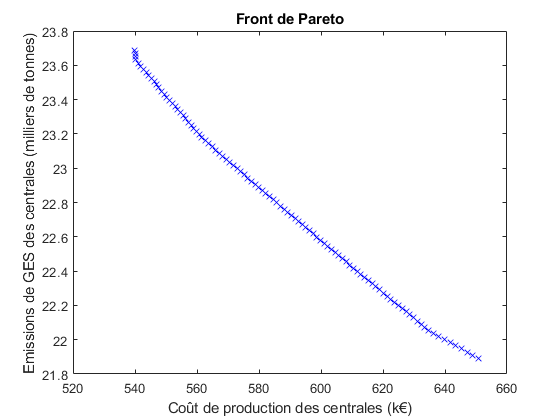

if useMultiObj
    Fval
    subplot(111)
    plot(Fval(1, :)*1e-3, Fval(2, :)*1e-3, 'bx')
    title("Front de Pareto")
    xlabel("Coût de production des centrales (k€)")
    ylabel("Emissions de GES des centrales (milliers de tonnes)")
end

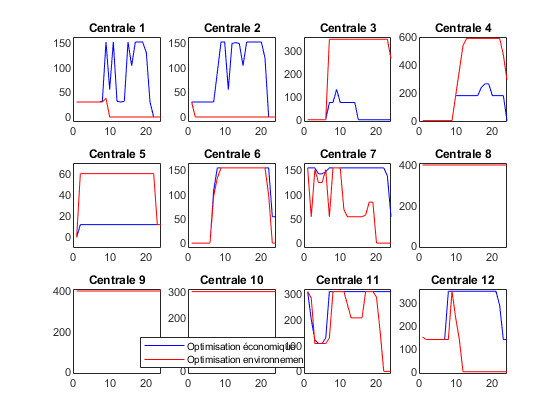

if useMultiObj
    % Plot puissances
    Psol1 = reshape(Xpareto(1:n, nbPoints), 24, 12);
    Psol2 = reshape(Xpareto(1:n, 1), 24, 12);
    for i=1:c
       subplot(3, 4, i)
       plot(1:h, Psol1(:, i), '-b', 1:h, Psol2(:, i), '-r')
       title(sprintf("Centrale %i", i))
       ylim([-10 dataC.Pmax(i)+10])
       if i==10
           legend(["Optimisation économique", "Optimisation environnementale"], "Location","best")
       end
    end
end

if useGlobal
    sum(besti)
    bestval
    Popsol
    X
end

Psol = reshape(xsol(1:n), 24, 12)

Psol =    30.4000   30.4000         0         0         0         0  155.0000  400.0000  400.0000  300.0000  310.0000  150.0350
   30.4000   30.4000         0         0   12.0000         0  155.0000  400.0000  400.0000  300.0000  202.0150  140.0000
   30.4000   30.4000         0         0   12.0000         0  155.0000  400.0000  400.0000  300.0000  122.5000  140.0000
   30.4000   30.4000         0         0   12.0000         0  142.4950  400.0000  400.0000  300.0000  108.5000  140.0000
   30.4000   30.4000         0         0   12.0000         0  142.4950  400.0000  400.0000  300.0000  108.5000  140.0000
   30.4000   30.4000         0         0   12.0000         0  147.5000  400.0000  400.0000  300.0000  130.0000  140.0000
   30.4000   30.4000   75.0000         0   12.0000  108.5700  155.0000  400.0000  400.0000  300.0000  310.0000  140.0000
   32.0000   90.4300   75.0000         0   12.0000  155.0000  155.0000  400.0000  400.0000  300.0000  310.0000  350.0000
  152.0000  152.0000  131

Rpsol = reshape(xsol(1+4*n:5*n), 24, 12)

Rpsol =    40.0000   40.0000         0         0         0         0   30.0000         0         0         0   27.5835   40.0000
   40.0000   40.0000         0         0   60.0000         0   26.9815         0         0         0         0         0
   40.0000   40.0000         0         0   60.0000         0   19.0300         0         0         0         0         0
   40.0000   40.0000         0         0   60.0000         0   16.3795         0         0         0         0         0
   40.0000   40.0000         0         0   60.0000         0   16.3795         0         0         0         0         0
   40.0000   40.0000         0         0   60.0000         0   19.0300         0         0         0         0         0
   40.0000   26.1370   70.0000         0   60.0000         0         0         0         0         0         0         0
   40.0000   40.0000   70.0000         0   60.0000         0         0         0         0         0         0   17.9430
   40.0000   40.0000   7

Rnsol = reshape(xsol(1+5*n:6*n), 24, 12)

Rnsol =    40.0000   40.0000         0         0         0         0   30.0000         0         0         0   27.5835   40.0000
         0   36.9815         0         0   60.0000         0   30.0000         0         0         0         0   40.0000
         0   29.0300         0         0   60.0000         0   30.0000         0         0         0         0   40.0000
         0   26.3795         0         0   60.0000         0   30.0000         0         0         0         0   40.0000
         0   26.3795         0         0   60.0000         0   30.0000         0         0         0         0   40.0000
         0   29.0300         0         0   60.0000         0   30.0000         0         0         0         0   40.0000
   40.0000   26.1370   70.0000         0   60.0000         0         0         0         0         0         0         0
         0   37.9430   70.0000         0   60.0000   30.0000   30.0000         0         0         0         0         0
         0   21.7975   7

[dataC.Rpos, dataC.CRpos]

ans =     40    15
    40    15
    70    10
   180     8
    60     7
    30    16
    30    16
     0     0
     0     0
     0     0


dataC.C

ans =    13.3200
   13.3200
   20.7000
   20.9300
   26.1100
   10.5200
   10.5200
    6.0200
    5.4700
         0


[dataC.Tini, dataC.UT, dataC.DT]

ans =     22     8     4
    22     8     4
    -2     8     8
    -1    12    10
    -1     4     2
    -2     8     8
    10     8     8
    50     1     1
    16     1     1
    24     0     0


% Contrainte RU
RU_ineq*xsol(1:2*n) - bRU_ineq

ans =  -165.6000
 -120.0000
 -120.0000
 -120.0000
 -120.0000
 -120.0000
 -120.0000
 -118.4000
         0
 -216.5200


% Contrainte RD
RD_ineq*xsol(1:2*n) - bRD_ineq

ans =   -74.4000
 -120.0000
 -120.0000
 -120.0000
 -120.0000
 -120.0000
 -120.0000
 -121.6000
 -240.0000
  -23.4800


% Contrainte Demande
D_eq*xsol(1:n) - bD_eq

ans = 	1.0e+-12 *

    0.2274
         0
    0.2274
    0.2274
    0.4547
    0.4547
    0.4547
    0.4547
         0
    0.4547


% Contrainte on/off
[Pmin_ineq ; Pmax_ineq]*xsol(1:2*n) - [bmin_ineq ; bmax_ineq]

ans =    -0.0000
         0
    0.0000
    0.0000
         0
         0
   -0.0000
   -1.6000
 -121.6000
  -25.0800


% Contraintes réserve
Rp_eq*xsol(1+3*n:4*n) - bRp_eq

ans =  -177.5835
 -166.9815
 -159.0300
 -156.3795
 -156.3795
 -159.0300
 -196.1370
 -227.9430
 -251.7975
 -254.4480


Rn_eq*xsol(1+3*n:4*n) - bRn_eq

ans =  -177.5835
 -166.9815
 -159.0300
 -156.3795
 -156.3795
 -159.0300
 -196.1370
 -227.9430
 -251.7975
 -254.4480


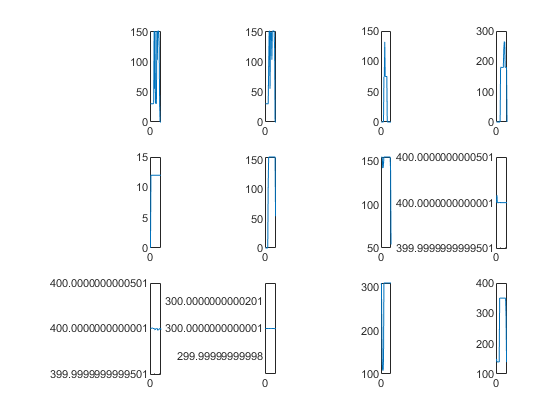

% Plot puissances
for i=1:c
    subplot(3, 4, i)
    plot(1:h, Psol(:, i))
end